clear
% #112
% Find the volume of a body bounded by surfaces
% hz=x^2+y^2, z=h
% V = int int int (T) dx dy dz

syms x y z h;
f1=(x^2+y^2)/h

$$f1 = \frac{x^{2}+y^{2}}{h}$$

% Transition to cylindrical coordinates
syms rho phi z;
J=rho;
f1=dec2cyl(f1)

$$f1 = \frac{\rho^{2}}{h}$$

% rho^2/h

V=int(int(int(J,z,rho^2/h,h),rho,0,h),phi,0,2*pi)

$$V = \frac{\pi \,h^{3}}{2}$$

% (pi*h^3)/2

% #113
% Find the coordinates of the center of gravity 
% of the prismatic body bounded by the planes
% x=0, z=0, y=1, y=3, x+2z=3

syms x y z;
V=int(int(int(1,z,0,(3-x)/2),y,1,3),x,0,3)

$$V = \frac{9}{2}$$

% 9/2
xm=1/V*int(int(int(x,z,0,(3-x)/2),y,1,3),x,0,3)

$$xm = 1$$

% 1
ym=1/V*int(int(int(y,z,0,(3-x)/2),y,1,3),x,0,3)

$$ym = 2$$

% 2
zm=1/V*int(int(int(z,z,0,(3-x)/2),y,1,3),x,0,3)

$$zm = \frac{1}{2}$$

% 1/2

% #114
% Find the volume of a body bounded by surfaces
% z=sqrt(x^2+y^2), z=x^2+y^2
% V = int int int (T) dx dy dz

syms x y z h;
f1=sqrt(x^2+y^2)

$$f1 = \sqrt{x^{2}+y^{2}}$$

f2=x^2+y^2

$$f2 = x^{2}+y^{2}$$

% Transition to cylindrical coordinates
syms rho phi z;
J=rho;
f1=dec2cyl(f1)

$$f1 = \left|\rho \right|$$

% (rho^2)^(1/2)
f2=dec2cyl(f2)

$$f2 = \rho^{2}$$

% rho^2

V=int(int(int(J,z,f2,f1),rho,0,1),phi,0,2*pi)

$$V = \frac{\pi }{6}$$

% pi/6

% #115
% Find the volume of a body bounded by surfaces
% z=0,
% cylindrical surface z=0.5*(x^2+y^2)
% and the sphere x^2+y^2+z^2=4

syms x y z;
z1=0.5*(x^2+y^2)

$$z1 = \frac{x^{2}}{2}+\frac{y^{2}}{2}$$

z2=sqrt(4-x^2-y^2)

$$z2 = \sqrt{-x^{2}-y^{2}+4}$$

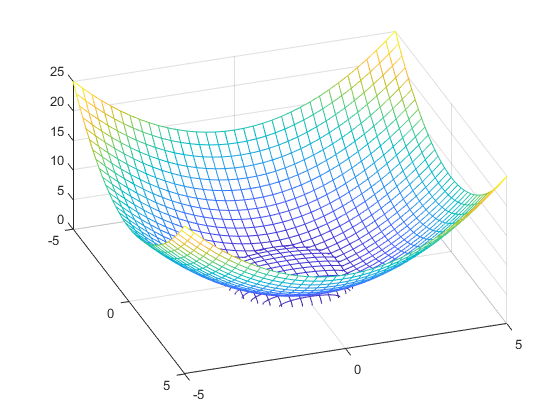

fmesh(z1)
hold on
fmesh(z2)
hold off

view([70.9 46.0])

% Transition to cylindrical coordinates
syms rho phi z;
J=rho;
z1=dec2cyl(z1)

$$z1 = \frac{\rho^{2}}{2}$$

z2=dec2cyl(z2)

$$z2 = \sqrt{4-\rho^{2}}$$

rho1=solve(z1==z2)

$$rho1 = \left(\begin{array}{c} \sqrt{2}\,\sqrt{\sqrt{5}-1}\\ -\sqrt{2}\,\sqrt{\sqrt{5}-1} \end{array}\right)$$

V1=int(int(int(J,z,0,z1),rho,0,rho1(1)),phi,0,2*pi)

$$V1 = -2\,\pi \,\left(\sqrt{5}-3\right)$$

V2=int(int(int(J,z,0,z2),rho,rho1(1),2),phi,0,2*pi)

$$V2 = \frac{16\,\pi \,\left(\sqrt{5}-2\right)}{3}$$

V=simplify(V1+V2)

$$V = \frac{2\,\pi \,\left(5\,\sqrt{5}-7\right)}{3}$$

% #116
% Find the cube mass
% 0<=x<=a, 0<=y<=a, 0<=z<=a
% gam=x+y+z

syms x y z a;
gam=x+y+z

$$gam = x+y+z$$

M=int(int(int(gam,z,0,a),y,0,a),x,0,a)

$$M = \frac{3\,a^{4}}{2}$$

% (3*a^4)/2

% #117
% Find the coordinates of the center of gravity 
% of a body bounded by surfaces
% x+y=1, z=x^2+y^2, x=0, y=0, z=0

syms x y z;
V=int(int(int(1,z,0,x^2+y^2),y,0,1-x),x,0,1)

$$V = \frac{1}{6}$$

% 1/6
xm=1/V*int(int(int(x,z,0,x^2+y^2),y,0,1-x),x,0,1)

$$xm = \frac{2}{5}$$

% 2/5
ym=1/V*int(int(int(y,z,0,x^2+y^2),y,0,1-x),x,0,1)

$$ym = \frac{2}{5}$$

% 2/5
zm=1/V*int(int(int(z,z,0,x^2+y^2),y,0,1-x),x,0,1)

$$zm = \frac{7}{30}$$

% 7/30

% #118
% Find the coordinates of the center of gravity 
% of a body bounded by surfaces
% z^2=x*y, x=5, y=5, z=0

syms x y z;
V=int(int(int(1,z,0,sqrt(x*y)),y,0,5),x,0,5)

$$V = \frac{500}{9}$$

% 500/9
xm=1/V*int(int(int(x,z,0,sqrt(x*y)),y,0,5),x,0,5)

$$xm = 3$$

% 3
ym=1/V*int(int(int(y,z,0,sqrt(x*y)),y,0,5),x,0,5)

$$ym = 3$$

% 3
zm=1/V*int(int(int(z,z,0,sqrt(x*y)),y,0,5),x,0,5)

$$zm = \frac{45}{32}$$

% 45/32

% #119
% Find the coordinates of the center of gravity 
% of a body bounded by surfaces
% 2x+3y-12=0, x=0, y=0, z=0, z=0.5y^2

syms x y z;
V=int(int(int(1,z,0,0.5*y^2),y,0,(12-2*x)/3),x,0,6)

$$V = 16$$

% 16
xm=1/V*int(int(int(x,z,0,0.5*y^2),y,0,(12-2*x)/3),x,0,6)

$$xm = \frac{6}{5}$$

% 6/5
ym=1/V*int(int(int(y,z,0,0.5*y^2),y,0,(12-2*x)/3),x,0,6)

$$ym = \frac{12}{5}$$

% 12/5
zm=1/V*int(int(int(z,z,0,0.5*y^2),y,0,(12-2*x)/3),x,0,6)

$$zm = \frac{8}{5}$$

% 8/5

% #120
% Find the moment of inertia of the cube
% 0<=x<=a, 0<=y<=a, 0<=z<=a
% with respect to its edge

syms x y z a;

Ix=int(int(int(y^2+z^2,z,0,a),y,0,a),x,0,a)

$$Ix = \frac{2\,a^{5}}{3}$$

% (2*a^5)/3
